# Lab #6 FIR Filtering of Nasal Air Temperature (Two Weeks)

## Objectives:

- Create a model of input data to provide a repeatable way to test and analyze filters

- Use fixed point representation scaling to allow faster calculations with improved resolution

- Use what you have learned about datatypes, execution time, and memory usage to optimize filter performance

- Learn how to create the filter kernel (impulse response) for a moving average filter and a windowed sinc filter

- Learn how to implement a FIR filter using convolution

- Learn how to modify a filtering algorithm (datatype, scaling, and length) to work within the limitations of a given digital signal processing chip 

## Reading

    Use  Chapters 14 & 16 in Smith for reference      

    Supplemental Reading -- "Resp Rate greater than 50 per minute as indicator of pneumonia”  

## Intended Learning Outcomes

- Demonstrate filtering of a signal using a FIR filter implemented in a microcontroller

- Demonstrate the ability to choose appropriate variable datatypes and signal scaling for those datatypes

- Practice communicating your results and your work in writing

### **Overview**

In this lab you will use your temperature sensor to measure nasal airflow temperature. The temperature of the air flowing over the sensor is low when you breathe in (drawing cool room air across the sensor) and high when you exhale (pushing air across the sensor that has been warmed by your lungs). The temperature output will look somewhat sinusoidal.

From the changing temperature signal, it is possible to determine a person’s respiration rate. A respiration rate of over 50 breaths per minute can be an indication of pneumonia. As we know from sampling theory, the sample rate for data collection must be at least twice this frequency to satisfy the Nyquist criteria.

In your data collection system, you will need to collect 256 samples of temperature readings, at a sampling interval of $T_s = 100$ milliseconds. This corresponds to a sampling frequency of 10 Hz.  At this rate the Nyquist frequency is:

####  
$$Nyquist Frequency = F_s/2 = 5Hz$$


This translates to a maximum detectable breathing rate of:

####  
$$Nyquist Frequency = 5Hz = 5 \frac{breaths}{Sec}$$


####  
$$5\frac{breaths}{sec}\times60\frac{Sec}{Min}=300\frac{breaths}{Min}$$


Which is much higher than the 50 breaths per minute requirement. With 256 samples, you will be collecting data over a time period of 25.6 seconds. 

The signal read from the LM61 temperature sensor contains quantization and analog noise. To get a good signal, two filtering steps are used. First, dithering and over sample averaging is utilized to get a "clean" signal from the ADC. An over-sample rate of 8 is used. This process takes about 6.5 milliseconds for each sample average. 

After the 256 samples of temperature data is retrieved from the ADC/averaging process, the samples are low-pass filtered. You will implement and compare the results of two different Finite Impulse Response (FIR) filters: a moving average (MAV) filter and a windowed SINC filter. Both of these FIR filters are implemented using convolution as shown in the figure below:

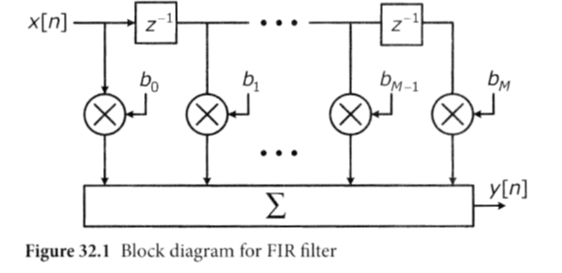

## **Section 1 -- Modeling of Breathing Data**

### **Section Discussion**

In this section you will capture real breathing data (or use a file with data already recorded for you). The data you capture will look sinusoidal in nature with some temperature drift. You are to create a model of the temperature data that you gathered by estimating the slope of the linear drift, the intercept of the drift, its sinusoidal frequency and amplitude and the amount of noise on the signal.  

You will capture temperature data in MATLAB and compute those values first in MATLAB and create a MATLAB model for the temperature. Then, you will implement the model of this signal with an equation within the Arduino C code. This model will be used as the input signal for other portions of the lab to provide a consistent signal for testing so that comparisons can be made between filtering operations.

### **Description of the code**

Use the code "CodeBase_Lab06_Section1_2225.ino" from myCourses and paste it into a new Arduino sketch. In `loop()`, 256 samples from the temperature sensor are collected and displayed. Each sample is the average of 8 dithered subsamples from the ADC. Each sample is converted to the ADC voltage and then converted to temperature in degrees Celsius using the conversion equation from the LM61 data sheet.  

### **Procedure**

***Collect real breathing data***

- Set up your system as done in Lab 4 to allow you to collect dithered and averaged sensor readings with ADC Vref = 5V.  Note that your dithering circuit must be connected correctly to the sensor.

- Breathe in a reasonably constant rhythm on the sensor at a slow rate, collect a sample set using MATLAB and plot the data.  With a little practice, you should obtain something like what is shown in the figure below. Slower breathing rates around one inhale and one exhale per second will produce a better set of data for you to work with.  **NOTE:  Alternately, you can use the data provided in the file: "Real_Breathing_Data.mat"**

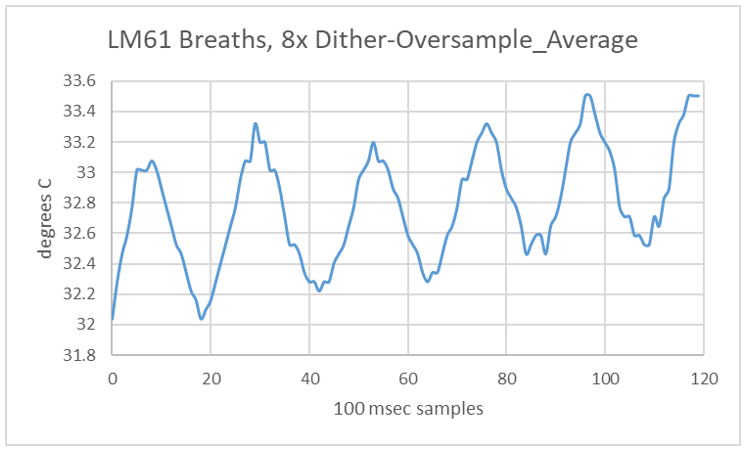

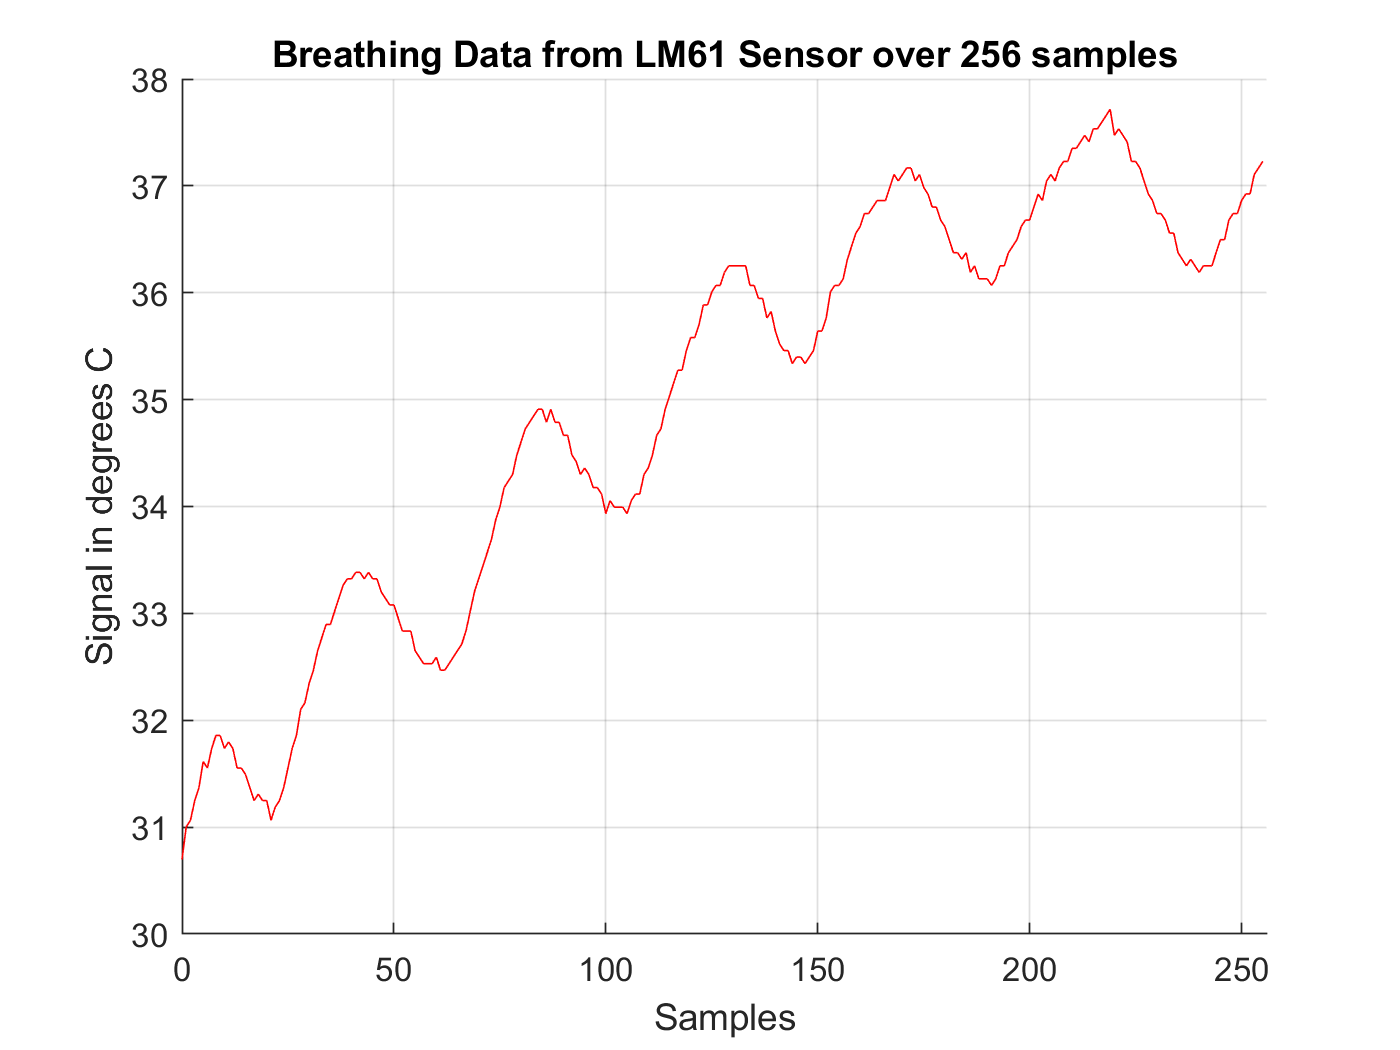

%  Load the breathing data that you recorded or use the example file
%  provided in myCourses

fileName = 'Real_Breathing_Data.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
temperature = outData(:,2);

%
%  Here is a summary of the steps to follow.  Place your code in the
%  section marked by SOLUTION
%
%  1.  Plot your data.  Title and label the plot
figure
grid on 
hold on
plot (sample, temperature, 'red')
xlim([0 256])
title('Breathing Data from LM61 Sensor over 256 samples')
xlabel('Samples')
ylabel('Signal in degrees C')

%  2.  Estimate the temperature drift as you have done in other labs using
%      the polyfit function.  Find the driftSlope and the driftIntercept
coeffs = polyfit(sample, temperature, 1);
slope = coeffs(1)

slope = 0.0243

intercept = coeffs(2)

intercept = 31.8653

driftEstimate = slope * sample + intercept

driftEstimate =    31.8653
   31.8896
   31.9139
   31.9381
   31.9624
   31.9867
   32.0110
   32.0353
   32.0596
   32.0839


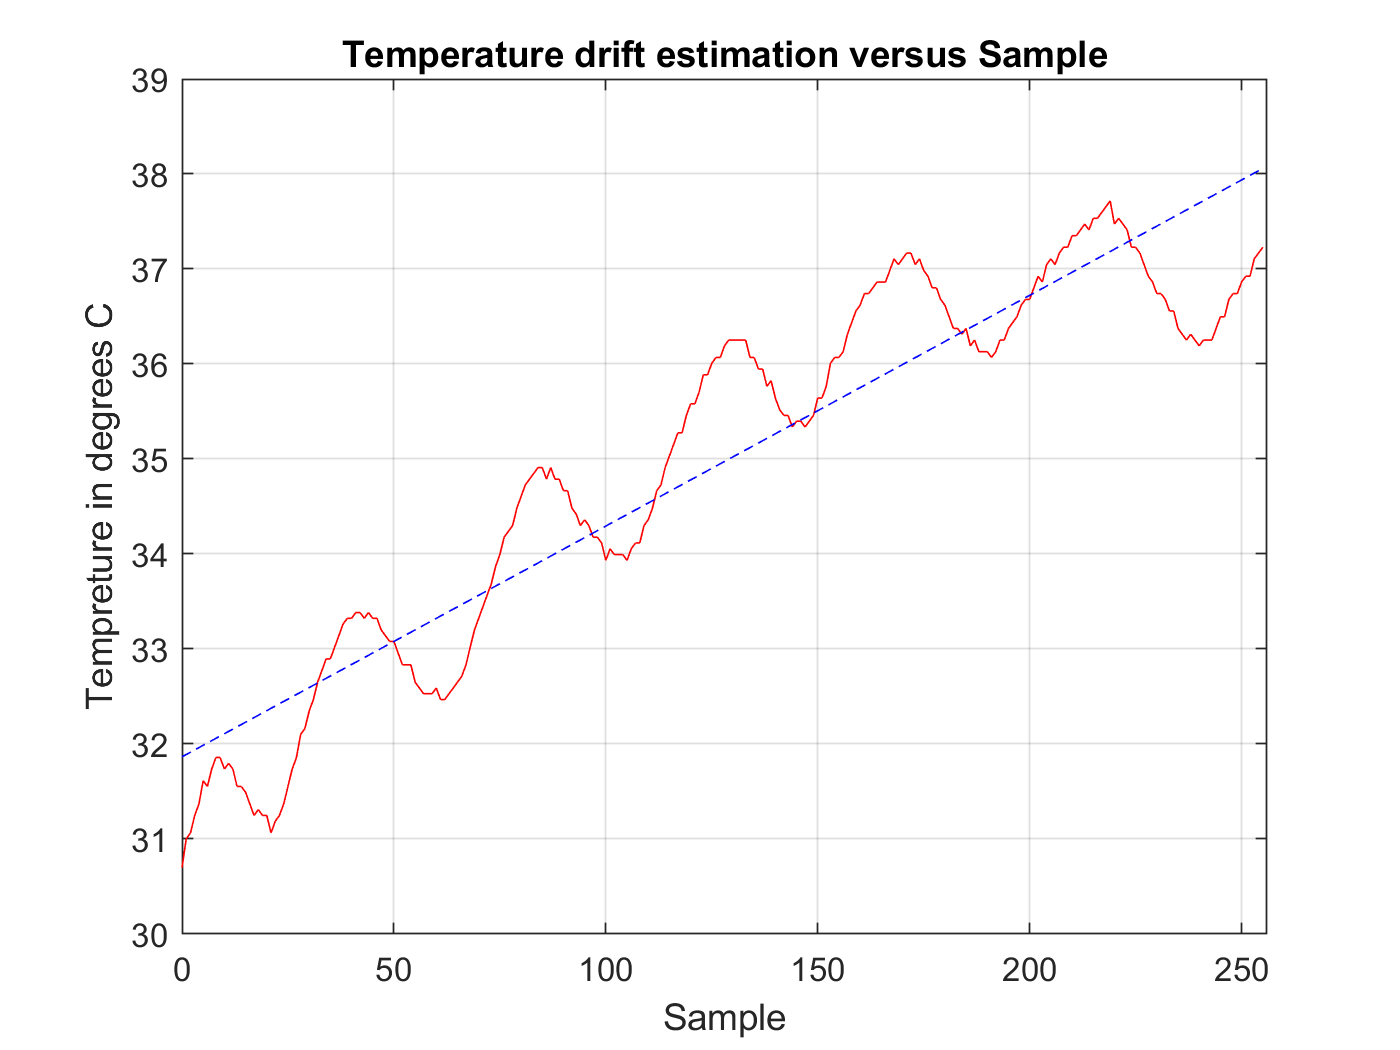


figure
plot (sample, temperature, 'red')
xlim([0 256])
grid on
hold on
plot(sample, driftEstimate, "Color", "blue", "LineStyle","--")
title('Temperature drift estimation versus Sample')
%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')
%  Label the Y-axis
ylabel('Tempreture in degrees C')

%  3.  Estimate the period of the breathing rate in samples per cycle
%      (samplesPerCycle).  Estimate this from a graph of the data with the drift
%      removed
signalNoDrift = temperature - driftEstimate

signalNoDrift =    -1.1673
   -0.8866
   -0.8499
   -0.6901
   -0.5924
   -0.3727
   -0.4580
   -0.2993
   -0.2016
   -0.2259


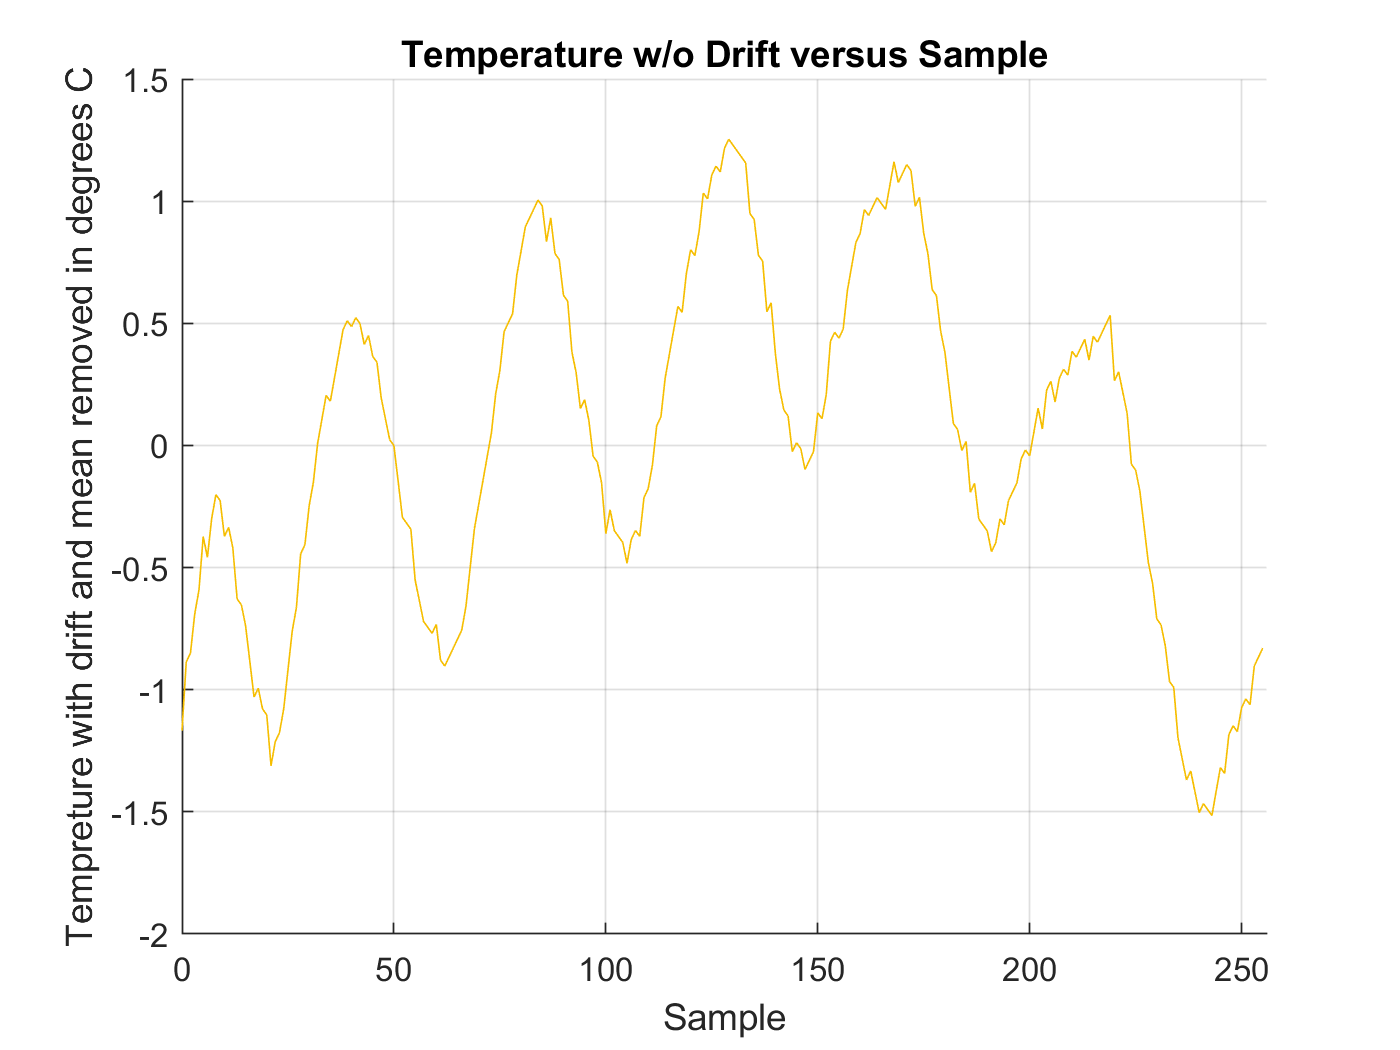


figure
grid on
hold on
plot(sample,signalNoDrift,"Color", '#F6BE00')
xlim([0 256])
%  Title the graph -- Use Descriptive titles
title('Temperature w/o Drift versus Sample')

%  Label the X-axis -- Use Descriptive labels
xlabel('Sample')

%  Label the Y-axis
ylabel('Tempreture with drift and mean removed in degrees C')

arrayTempAmps = [-0.201584, 0.522942, 1.0046, 1.25368, 1.16148, 0.532841];
DifferenceEl = diff(arrayTempAmps)

DifferenceEl =     0.7245    0.4817    0.2491   -0.0922   -0.6286


period = mean(DifferenceEl) % in seconds 42 samples

period = 0.1469


%  4.  Estimate the peak amplitude of the sinusoid (tempP).  Estimate this from a graph of the data with the drift
%      removed
arrayTempPeakToPeak = [1.109736, 1.401742, 1.487031, 1.3521687, 1.5966, 2.047891]

arrayTempPeakToPeak =     1.1097    1.4017    1.4870    1.3522    1.5966    2.0479


Amplitude = mean(arrayTempAmps)

Amplitude = 0.7123

%  5.  Estimate the noise on the signal represented as a standard
%      deviation.
noise = std(temperature)

noise = 1.9303

SigmaNoiseNoDrift = std(signalNoDrift)

SigmaNoiseNoDrift = 0.7015

%  1.  Plot the original data

%  SOLUTION

% 2.   Determine the drift parameters (linear).  Create a drift estimate and
%      remove the drift.  Plot the temperature with the drift removed.


% SOLUTION



%  3.  Estimate the period of the breathing rate from the graph in samples per
%  cycle.  Convert this to breaths per minute (bpm) using:
%
%  bpm = 1/samplesPerCycle * 10 Samples/Sec * 60 Sec/Min
%
%  Create a variable that represents the period of breathing in breaths per
%  minute

bpm = 1/period * 10 * 60

bpm = 4.0848e+03


%  4. Estimate the peak amplitude (tempP) of the sinusoid from the graph.
%  Create a variable that represents the peak amplitude of the temperature
%


%  SOLUTION



***Create a repeatable model of the breathing data***

In the following exercises, you will examine the effects of various filter designs on breathing signals like this. In order to make meaningful conclusions about comparative filter performance, you need a repeatable breathing signal. You will model the breathing signal using an equation that includes a time varying temperature, temperature drift and noise:

####  
$$T = T_0 +T_{drift}*n+T_{p}sin(2\pi\times n/(\frac{samples}{cycle}))+T_{noise}$$


Where $T_0$  is the average temperature (drift intercept), $T_{drift}$  is the rate of temperature drift (drfit slope), $T_{p}$ is the peak temperature variation, samples per cycle is the period of the breathing rate,   $T_{noise}$ is uniformly distributed noise and n is the sample number.



%  Create a model of the signal in MATLAB so that you can compare it to the
%  real breathing data. You can then use these parameter estimates in your C
%  code and again compare to make sure your C code is correct
%
%  The signal model equation uses samplesPerCycle. The C code will do the
%  conversion from bpm to samplesPerCycle for later convenience
%
%  First create the signal model equation without noise. This will allow
%  you to check the slope and frequency
%
noiseUniform = ( rand(length(sample),1) -.5 )/.29;   %  Uniform random  with SD of 1 degC
tempModelWithoutNoise = intercept + slope * sample + Amplitude*sin(2*pi*sample/period);
%
%  Plot the temperature model and the real breathing data on the same graph

%  SOLUTION


%  5.  Estimate the standard deviation of the noise 
%
%  Now add noise.  The noise is a uniform random variable with a SD of 1
%  degC. It is scaled by your value of sigma, which you will determine
%  empirically (manually adjust the value). Add the uniform noise to the
%  your model as shown below
%
%  Create a variable that is a uniform random variable with a SD of 1 deg C
%
%  This noise value will be scaled by a variable sigma so that you can
%  adjust the noise level. You will adjust this manually to match the real
%  breathing signal captured in lab
%

tempModelWithNoise = intercept + slope * sample + Amplitude*sin(2*pi*sample/period) + SigmaNoiseNoDrift * noiseUniform

tempModelWithNoise =    32.9818
   31.8589
   30.2474
   32.7005
   33.1685
   32.5160
   31.5568
   30.7609
   32.8765
   32.1312


% sigma might be 0.5
%
%
%  Plot the model equation on top of the real breathing data for comparison.
%  It doesn't have to be exact, something close will be fine. Adjust the
%  noise "sigma" empirically to be close.

%  SOLUTION



***Use the default model of breathing data - in the arduino***

Create a signal model in the C code by comment deselecting `analogReadDitherAveDegC() `and comment selecting `simulateBreathingDegC()`as the sample source. The simulation return is composed of a constant level (room temperature) plus a ramp (warm up drift) plus a sine wave (breathing temperature cycle) plus a random variable (sensor noise). Enter the variables that you calculated in MATLAB into the C code. Run the sketch and plot the simulated breathing output and compare it to the real breathing data and the MATLAB model.

Include the values of your breathing rate model in your lab report.

%
%  Once you have found acceptable values for the model, transfer those
%  values to the C Code. Run the C-code model and capture this "data" in MATLAB.
%  Plot all three temperature plots on the same graph to compare

% SOLUTION



***Run the model faster than normal by changing ***`TSAMP_MSEC`

- Set `TSAMP_MSEC` = 10 and observe that the model output is unchanged.  This is just done to decrease the amount of time to get a full display. 

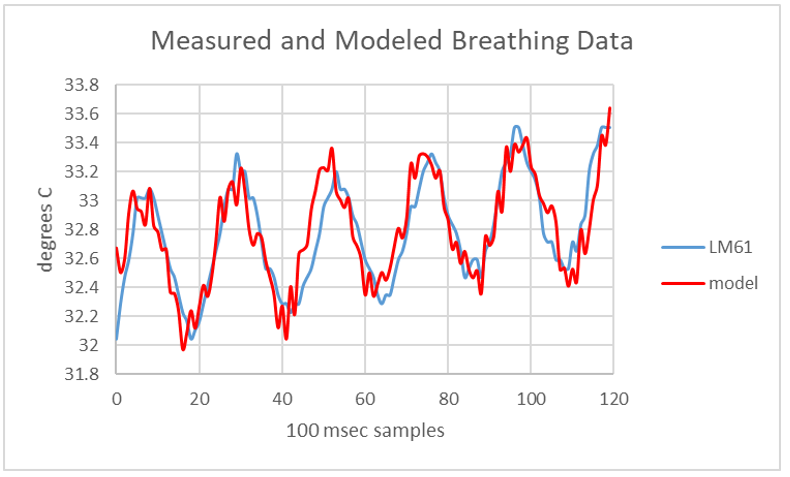

## **Section 2 – Fixed point data representation and scaling**

### **Section Description**

In this section you will use the breathing model that you created in section 1 and collect data in different ways to show how this data can be represented as float and a fixed point numbers even containing a fractional portion.

Recall that floating point numbers can represent numbers with fractions. Fixed point numbers can only directly represent integer values. However, if we take a floating point number with a fractional portion, we can scale that number by factors of 10 (10,100,1000,...) and then use a fixed point number to represent the fractional number as long as we keep track of the scale factor.

For example, if we have a floating point number 33.4582 and convert it to a fixed point value, it will be represented as 33. If it is scaled by a factor of 10 first and then converted to fixed point, it will be represented by 334 which represents the value 33.4 when scaled back down. If it is scaled by 100 and then converted to fixed point, it will be represented by 3345 which represents 33.45 when scaled back down by 100. In this manner, we can used fixed point numbers to represent fractional values.

Note that when the conversion to a fixed point number is completed, there is a rounding process that happens which leads to some amount of error or quantization noise. Also, when scaling the number we also have to be careful not to scale it by so much  that it cannot be represented properly in the fixed point number system we have chosen.

***Why fixed point?***

From Lab 5, you know that integer and long datatype computations are much faster than floating point computations. Fixed point arithmetic enables integer storage of data by rescaling units to the finest precision value required for a problem, and then choosing an integer data type (`int `or `long`) to cover the required range.

*An illustration of the technique*

Temperature measurements in our DSP system exhibit an SNR no better than about 30 dB (~32:1) for a 1 °C pk-pk amplitude square wave temperature excursion, so there is no need to represent incremental temperatures less than 0.01°C or 1 centi-degree Celsius (cC). Assume a working temperature range of -10 °C to +50 °C or -1000 cC to +5000 cC. Now, we can represent all meaningful temperatures with integer variables (INTs) with a resolution of 1 cC. For example, the floating point value 27.73 °C is stored as the integer 2773 cC. Each sample measurement now requires just 2 bytes of memory for an INT instead of 4 bytes for a FLOAT, and computational speed is improved.

If the SNR of the sensor were 60 dB, we would choose a unit of 0.001C or 1 milli-degree Celsius (mC). The operational range would be -10,000 mC to +50,000 mC, so a datatype of LONG variables would be required to store the number because they would exceed the range of an INT. Each measurement value would require the same 4 bytes as it would if it were stored as a FLOAT, but computational speed would still be improved.

### Description of the code

For this section of the lab, start with the code file in myCourses named "CodeBase_Lab06_Section2_2225.ino". This code uses the model of the temperature sensor from section 1 with some modifications to the parameter values.

This code returns 4 values for each sample gathered. The 1st column is the sample number, the 2nd column is a floating-point number representing the temperature. This is the variable fltX in the C code.

The 3rd column is also a floating point number, but it is the temperature value scaled by a constant in the code DATA_FXPT which will be set to 1, 10, 100 and 1000 during the procedure steps. It is the variable scaleFltX in the C code.

The 4th column is a fixed point number that is the scaled floating point number converted to an integer value. The conversion to fixed point rounds the value to the nearest integer and will effectively add quantization noise to the value. It is the variable fxptX in the C code.

The 5th column of data is the difference between the scaled floating point number in column 3 and the fixed point value in column 4.  

### **Procedure**

1. Modify the breathing temperature model parameters so that the signal has an average value of 33 °C (driftIntercept = 33.0),  no drift (driftSlope = 0.0), no noise (sigma = 0.0) and a breathing rate of 10 bpm with a magnitude of 0.6 °C peak.

2. Start with the value of DATA_FXPT set to 1. Run the Arduino code and capture data in MATLAB. Column 5 contains the error between the scaled fixed-point value and the scaled floating-point value. Compute the standard deviation of this error. This is the noise of the signal. Calculate the signal level by computing the standard deviation of the scaled floating-point value in column 3.

Repeat the measurements for DATA_FXPT = 10, 100, and 1000, respectively. Complete a table of your results like the one shown below. Include a short paragraph in your report interpreting your results.

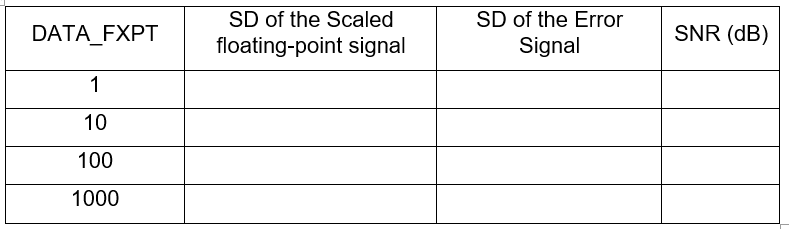

3. Plot an overlay of scaled float-point values and the scaled fixed point values for each value of the scale factor.  Plot the associated quantization error plots in the manner shown below for DATA_FXPT = 1 to inform your understanding.  The error plots need not be included in your report.

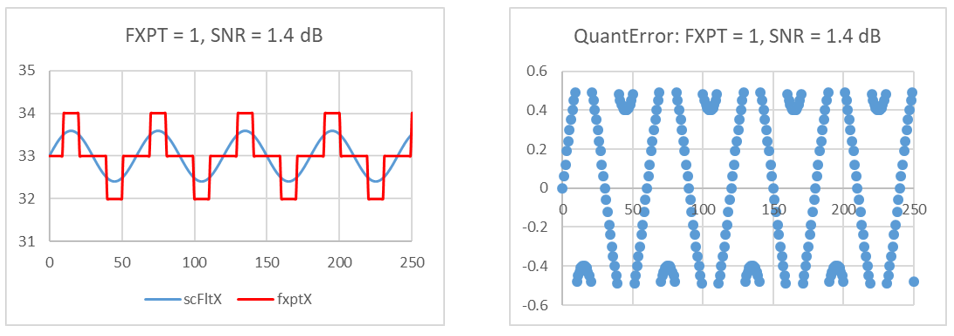

%  For each value of DATA_FXPT  Capture data and compute the standard
%  deviation of the error and the standard deviation of the scaled floating
%  point signal.  Plot the scaled fixed point value and the fixed point
%  value on the same graph for each value of DATA_FXPT


%  SOLUTION DATA_FXPT = 1




%  SOLUTION DATA_FXPT = 10



%  SOLUTION DATA_FXPT = 100


%  SOLUTION DATA_FXPT = 1000


